## Q_04 Simulation Report

Given the following topology, 

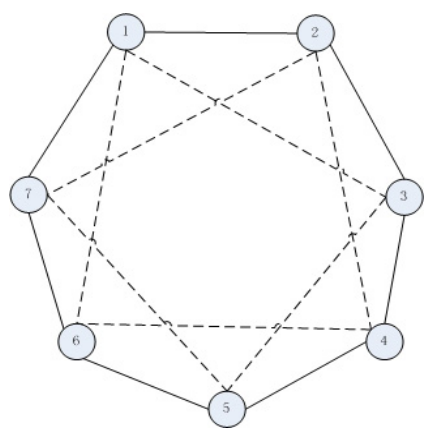

the multi-agent system would be simulated in MATLAB Simulink as in the following figure.

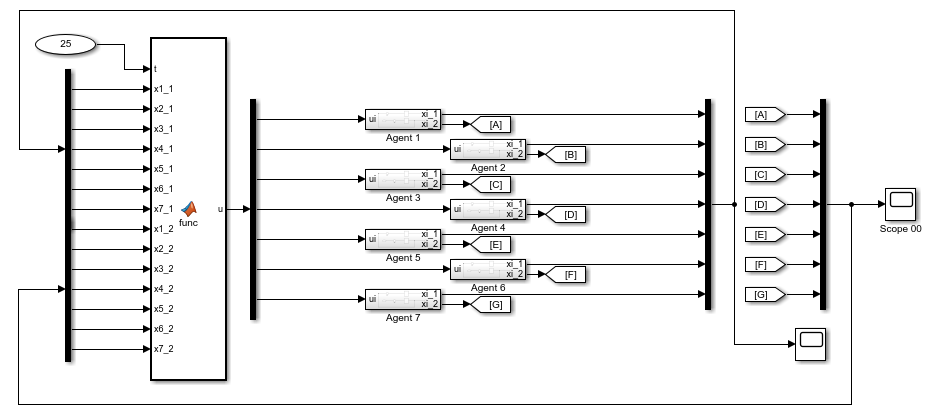

### Agent Dynamics Simulation

Each agent is desigined within a subsystem block in which two integrator states are considered as given in the problem. The control signal is the only input to the agents and the outputs are agents' states.

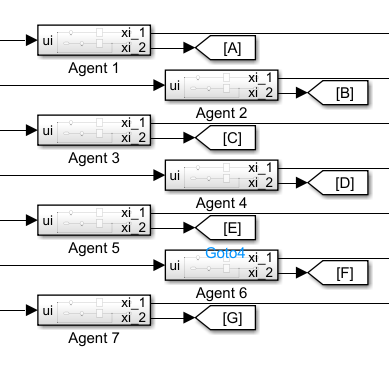

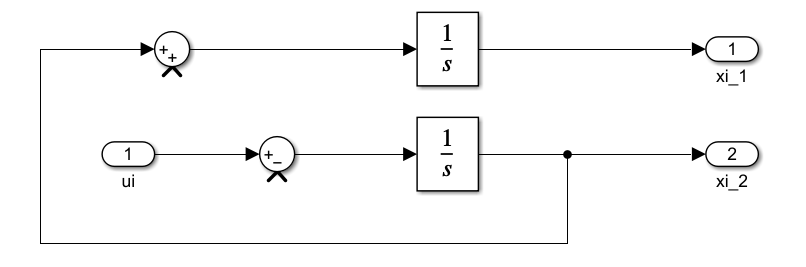

Also the following values have been set as the initial conditions of each agent states.


$$\mathrm{Agent}\;1:x_1 \left(0\right)=3\ldotp 5\;\;\;\;\;|\;\;\;x_2 \left(0\right)=-1$$



$$\mathrm{Agent}\;2:x_1 \left(0\right)=2\;\;\;\;\;\;\;\;\;\;|\;\;\;x_2 \left(0\right)=-1\ldotp 5$$



$$\mathrm{Agent}\;3:x_1 \left(0\right)=3\;\;\;\;\;\;\;\;\;\;|\;\;\;x_2 \left(0\right)=\;\;-1\ldotp 2$$



$$\mathrm{Agent}\;4:x_1 \left(0\right)=3\ldotp 7\;\;\;\;\;|\;\;\;x_2 \left(0\right)=\;\;\;1\ldotp 7$$



$$\mathrm{Agent}\;4:x_1 \left(0\right)=2\ldotp 2\;\;\;\;\;|\;\;\;x_2 \left(0\right)=\;\;\;1\ldotp 8$$



$$\mathrm{Agent}\;4:x_1 \left(0\right)=3\ldotp 2\;\;\;\;\;|\;\;\;x_2 \left(0\right)=\;\;\;1\ldotp 4$$



$$\mathrm{Agent}\;4:x_1 \left(0\right)=3\ldotp 3\;\;\;\;\;|\;\;\;x_2 \left(0\right)=\;\;\;1\ldotp 9$$


### Agents Input

Each agent input is of Control Signal type. The control signal is derived from the presented control protocol of the MAS.

The available MATLAB Function block in which the control protocol is implemented provides the agents with the control signal term.

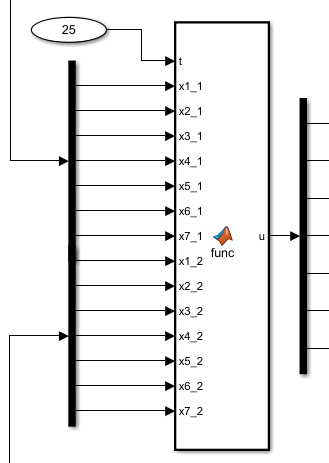

There you could find how the control protocol is implemented. Also you could find the script in the following:

function u = func(t, x1_1, ...
                     x2_1, ...
                     x3_1, ...
                     x4_1, ...
                     x5_1, ...
                     x6_1, ...
                     x7_1, ...
                     x1_2, ...
                     x2_2, ...
                     x3_2, ...
                     x4_2, ...
                     x5_2, ...
                     x6_2, ...
                     x7_2)

states_1 = [x1_1, x2_1, x3_1, x4_1, x5_1, x6_1, x7_1, ]';
states_2 = [x1_2, x2_2, x3_2, x4_2, x5_2, x6_2, x7_2, ]';
numSates = 7;

L_1st_neighbour = [  2,-1,0,0,0,0,-1;
                     -1,2,-1,0,0,0,0;
                     0,-1,2,-1,0,0,0;
                     0,0,-1,2,-1,0,0;
                     0,0,0,-1,2,-1,0;
                     0,0,0,0,-1,2,-1;
                     -1,0,0,0,0,-1,2;];

L_tilda = [ 4 -1 -1  0  0 -1 -1;
           -1  4 -1 -1  0  0 -1;
           -1 -1  4 -1 -1  0  0;
            0 -1 -1  4 -1 -1  0;
            0  0 -1 -1  4 -1 -1;
           -1  0  0 -1 -1  4 -1;
           -1 -1  0  0 -1 -1  4;
           ];

L_2nd_neighbour = L_tilda - L_1st_neighbour;

eigLtilda = eig(L_tilda);
eigLtilda = sort(round(eigLtilda*1000)/1000);

eigL1st = eig(L_1st_neighbour);
eigL1st = sort(round(eigL1st*1000)/1000);

gamma_1 = 1;
gamma_2 = sqrt(4*gamma_1/eigLtilda(2));

u =  real(-gamma_1*L_1st_neighbour*states_1 - gamma_2*L_1st_neighbour*states_2 - gamma_1*L_2nd_neighbour*states_1 - gamma_2*L_2nd_neighbour*states_2);

end

First, the Laplacian matrix of the given topology considering the first-order neighbours is formed in `L_1st_neighbour` , considering first-order and second-order neighbours in `L_tilda`  and the states vectors are set up. Hence, the corresponding Laplacian matrix according to the second-order neighbours obtains in `L_2nd_neighbour = L_tilda - L_1st_neighbour`. Finally the algorithm protocol is presented and the control signal is defined as the output of the function.

### Run and Simulate

Running the simulation for 25 seconds leads into the following results:

- **1st-order neighbours only (case 0)**


$$x_1 :$$


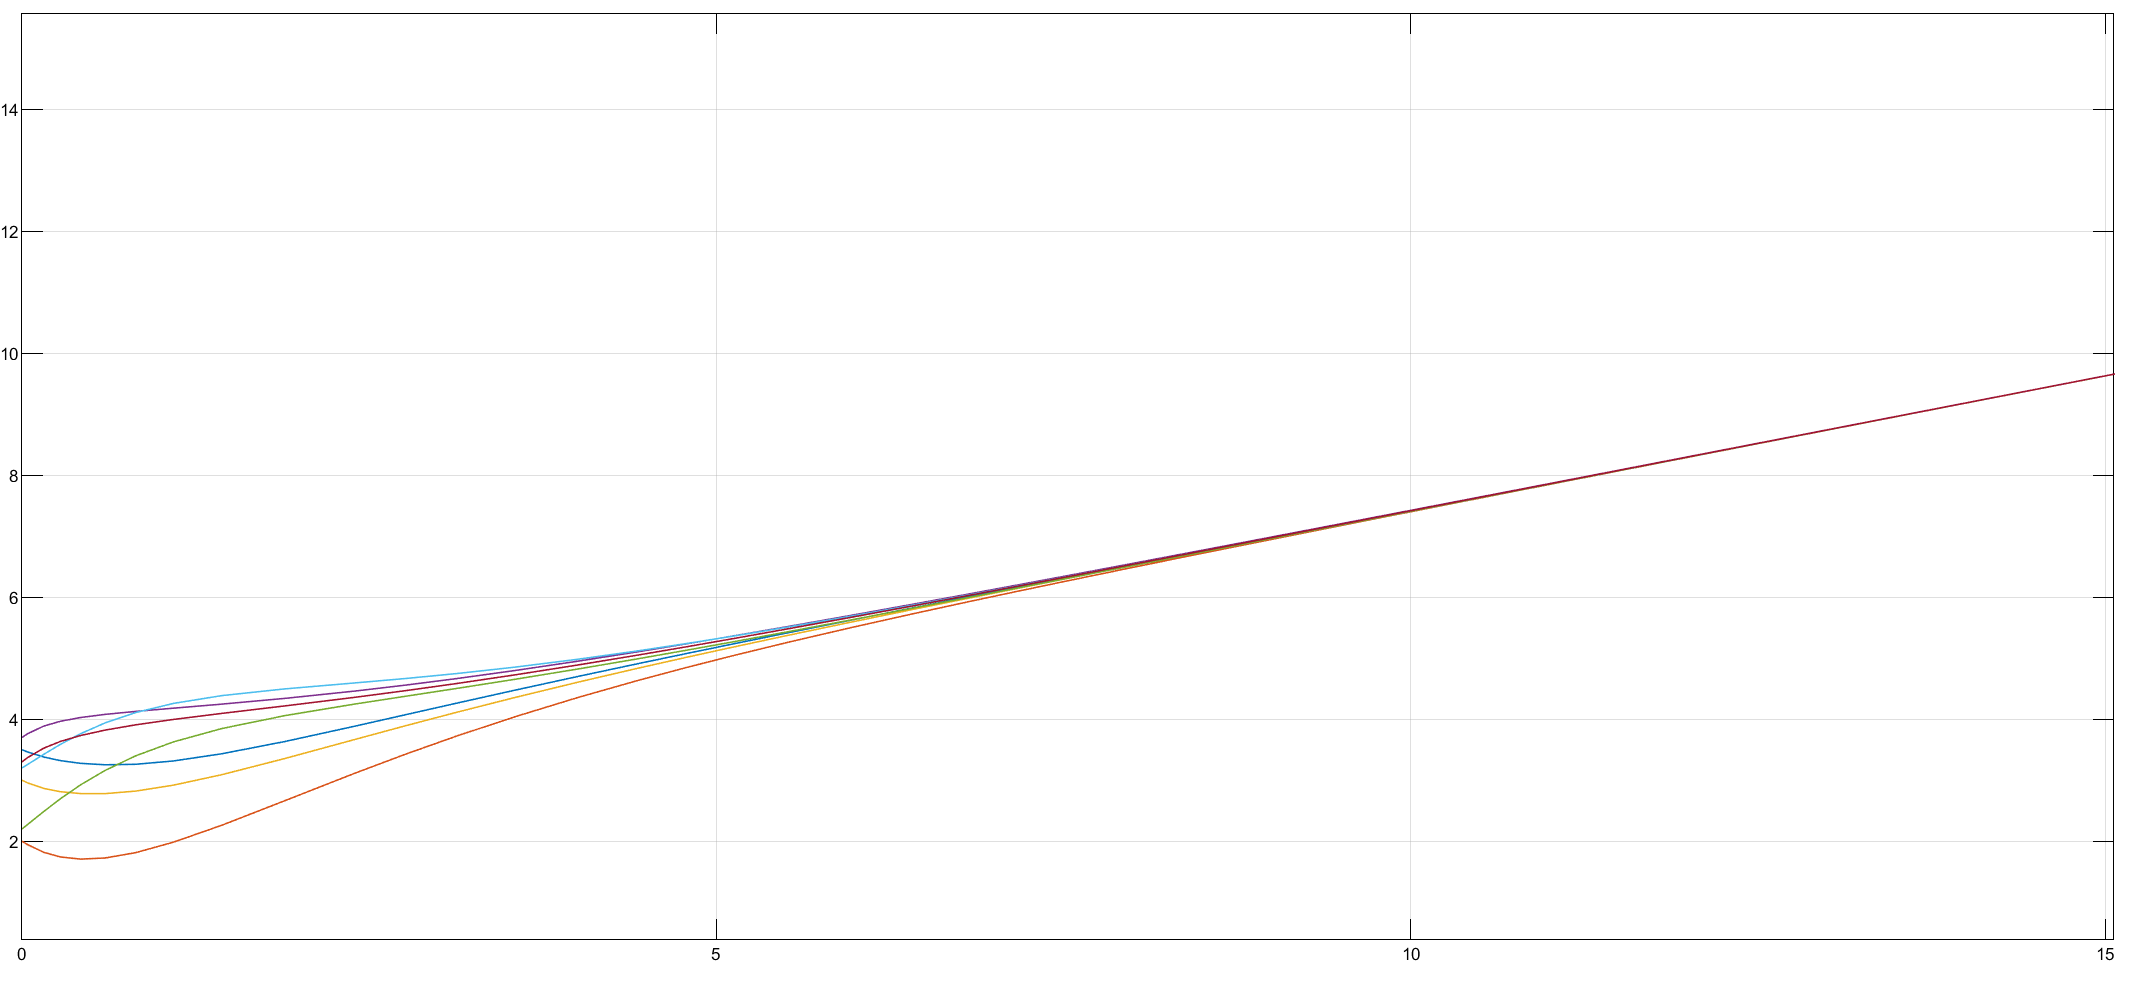


$$x_2 :$$


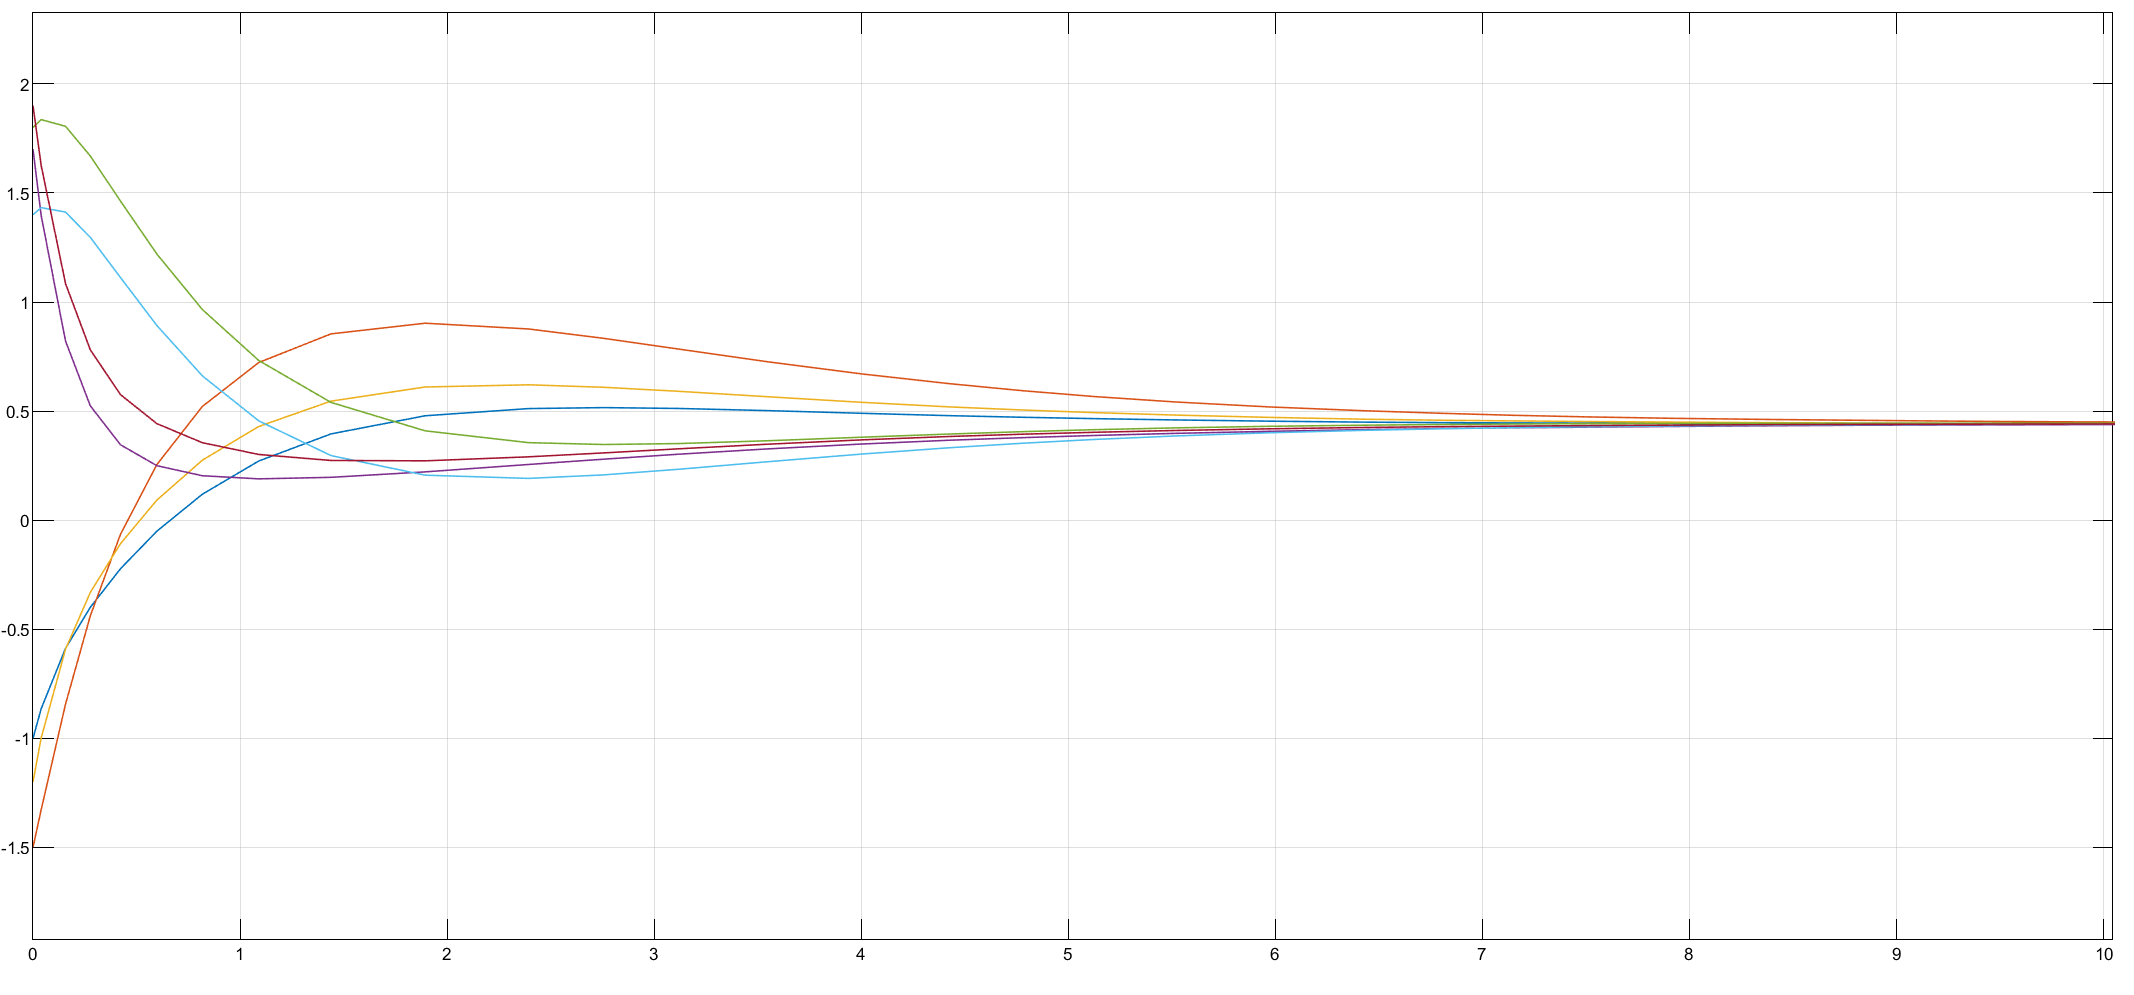

- **1st&2nd-order neighbours (case I)**


$$x_1 :$$


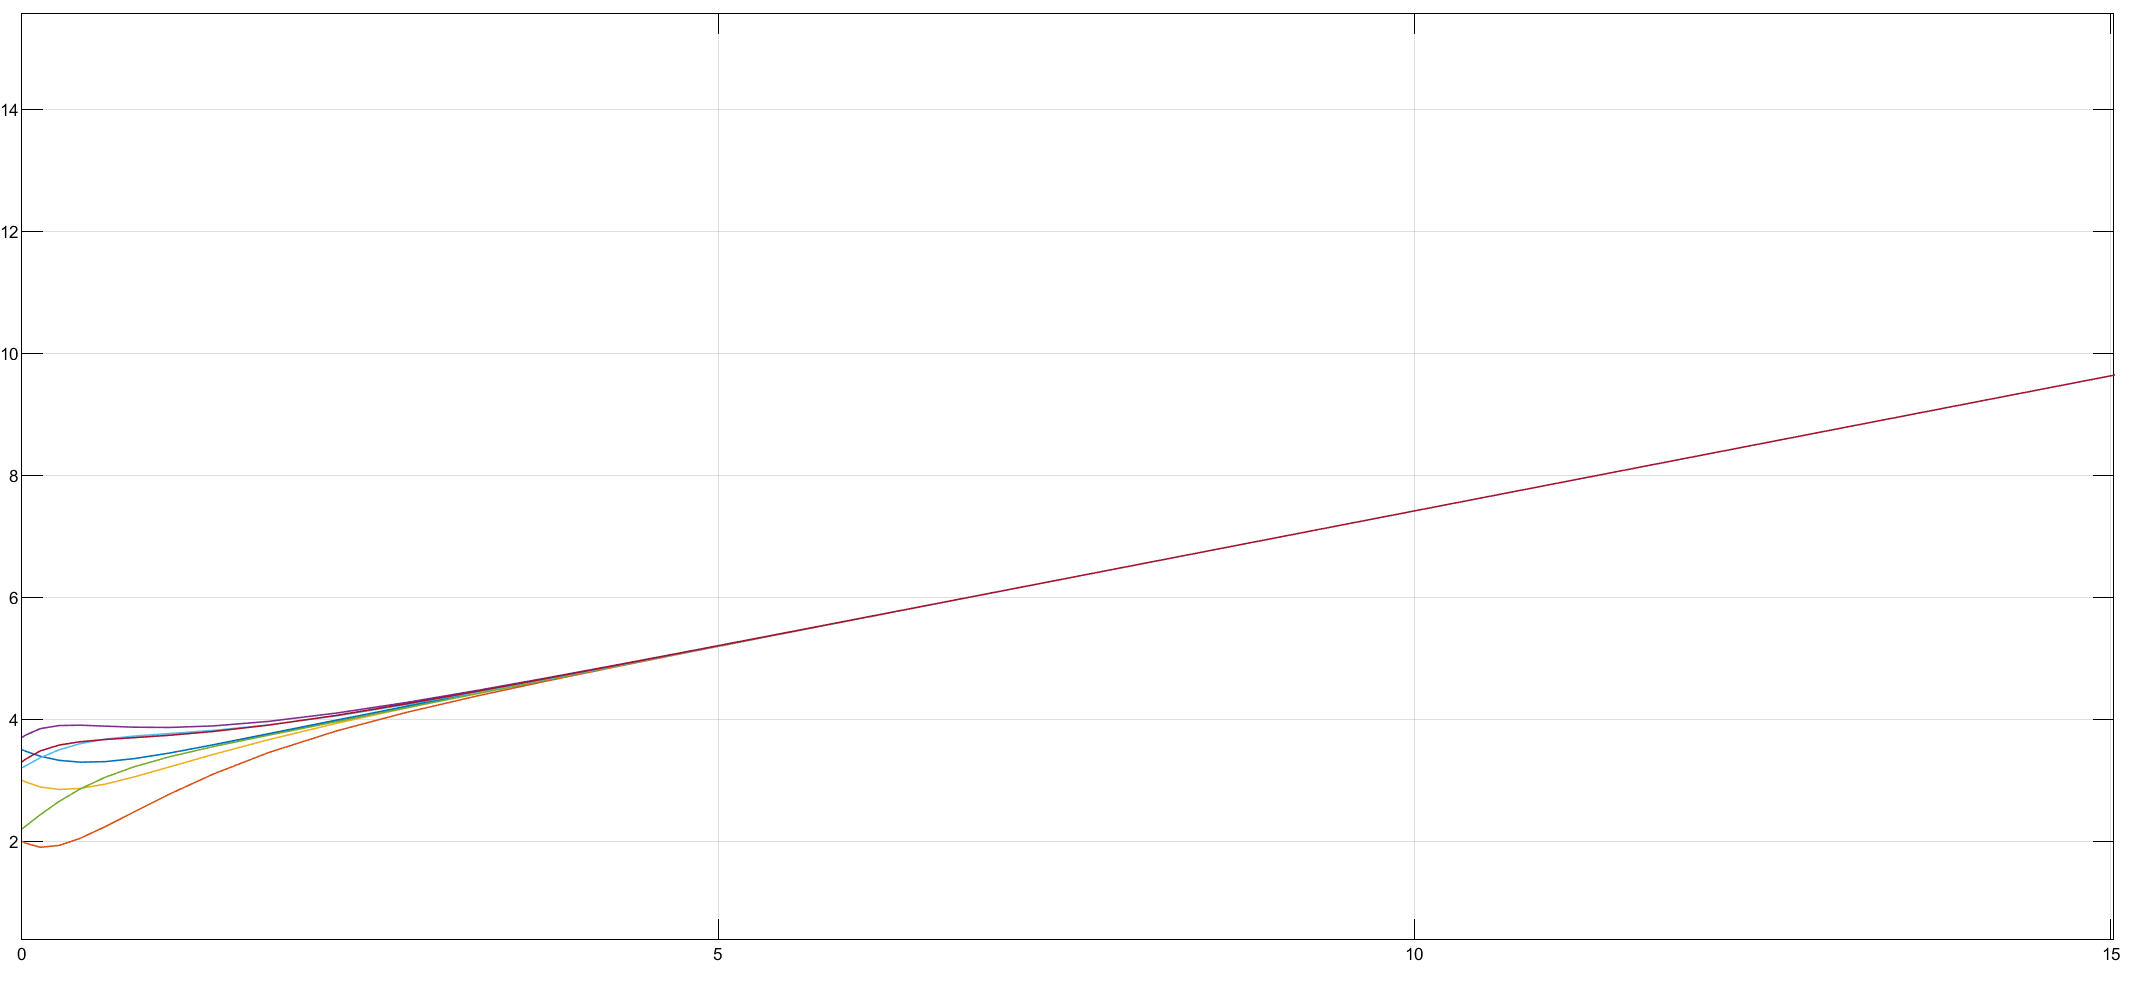


$$x_2 :$$


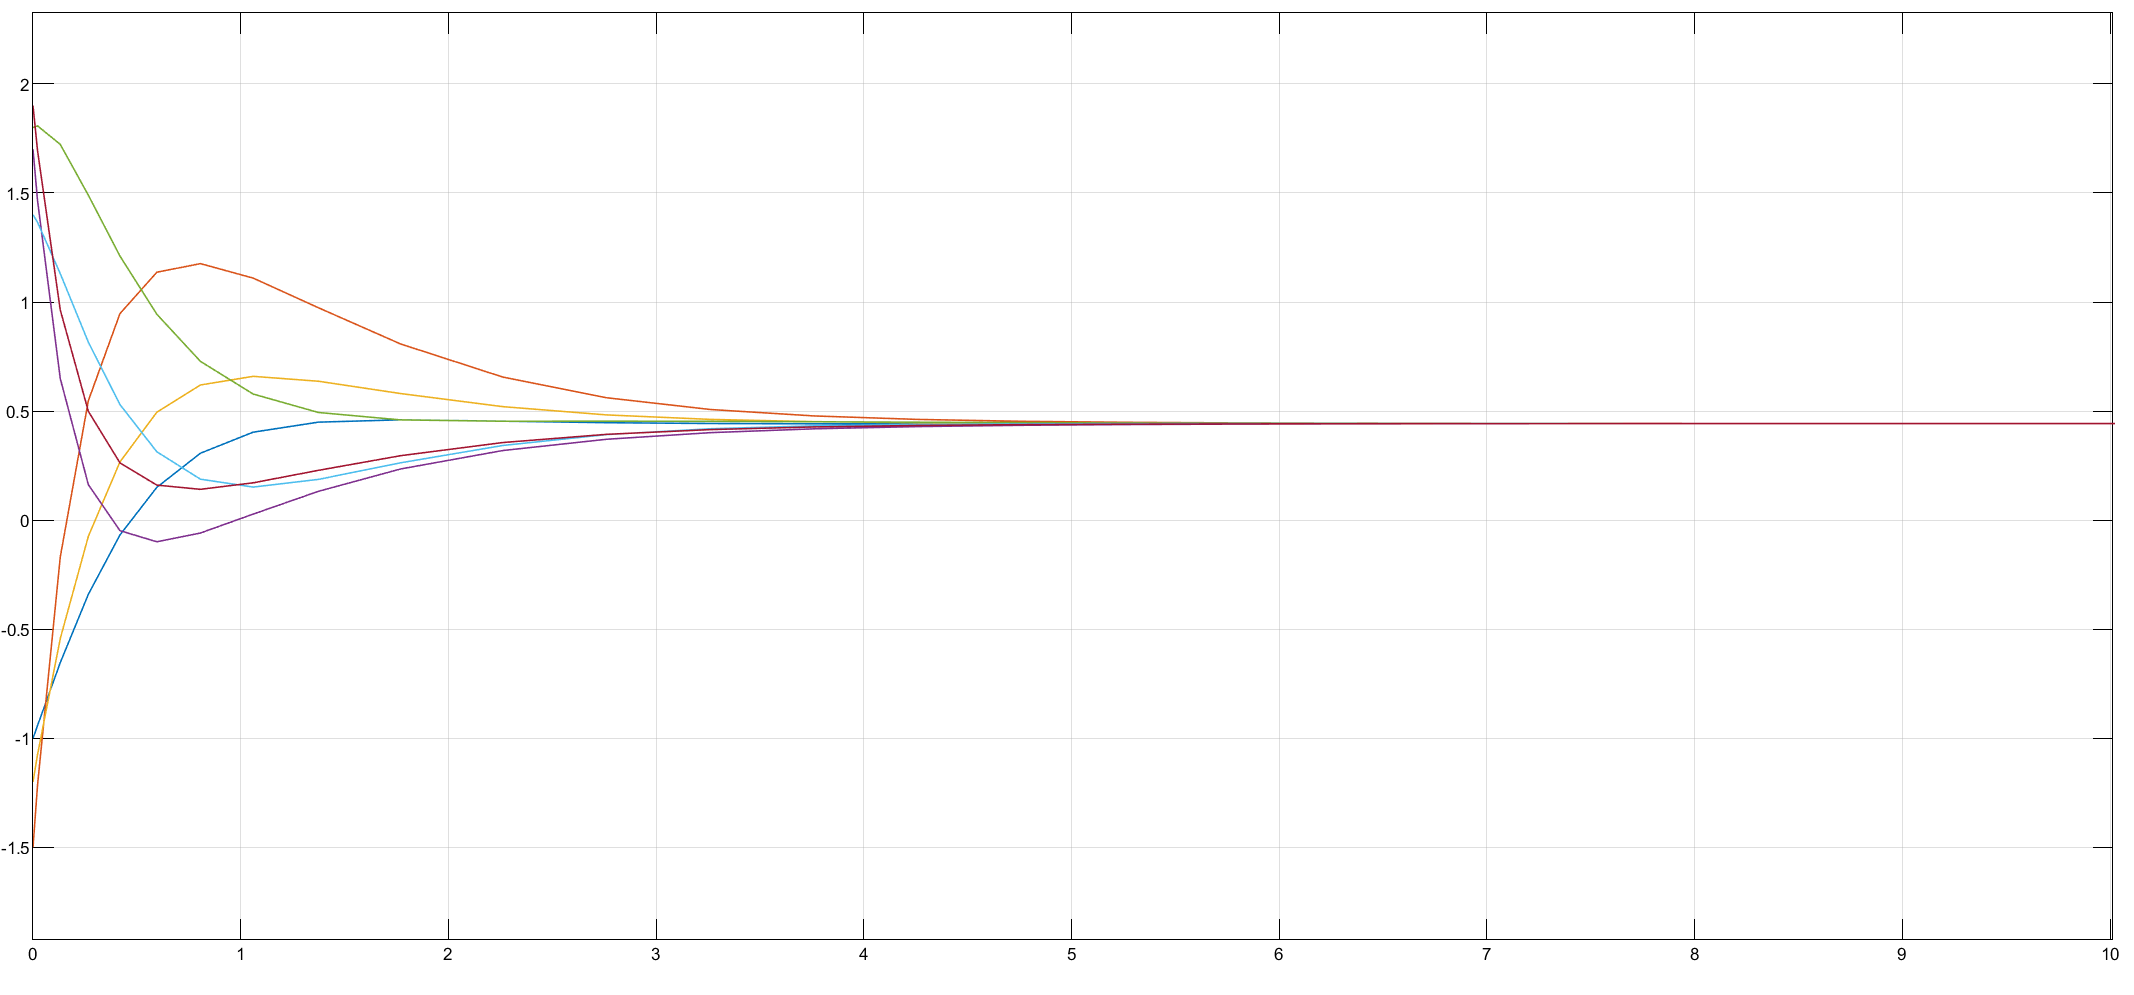

- **1st&2nd-order neighbours (case II)**


$$x_1 :$$


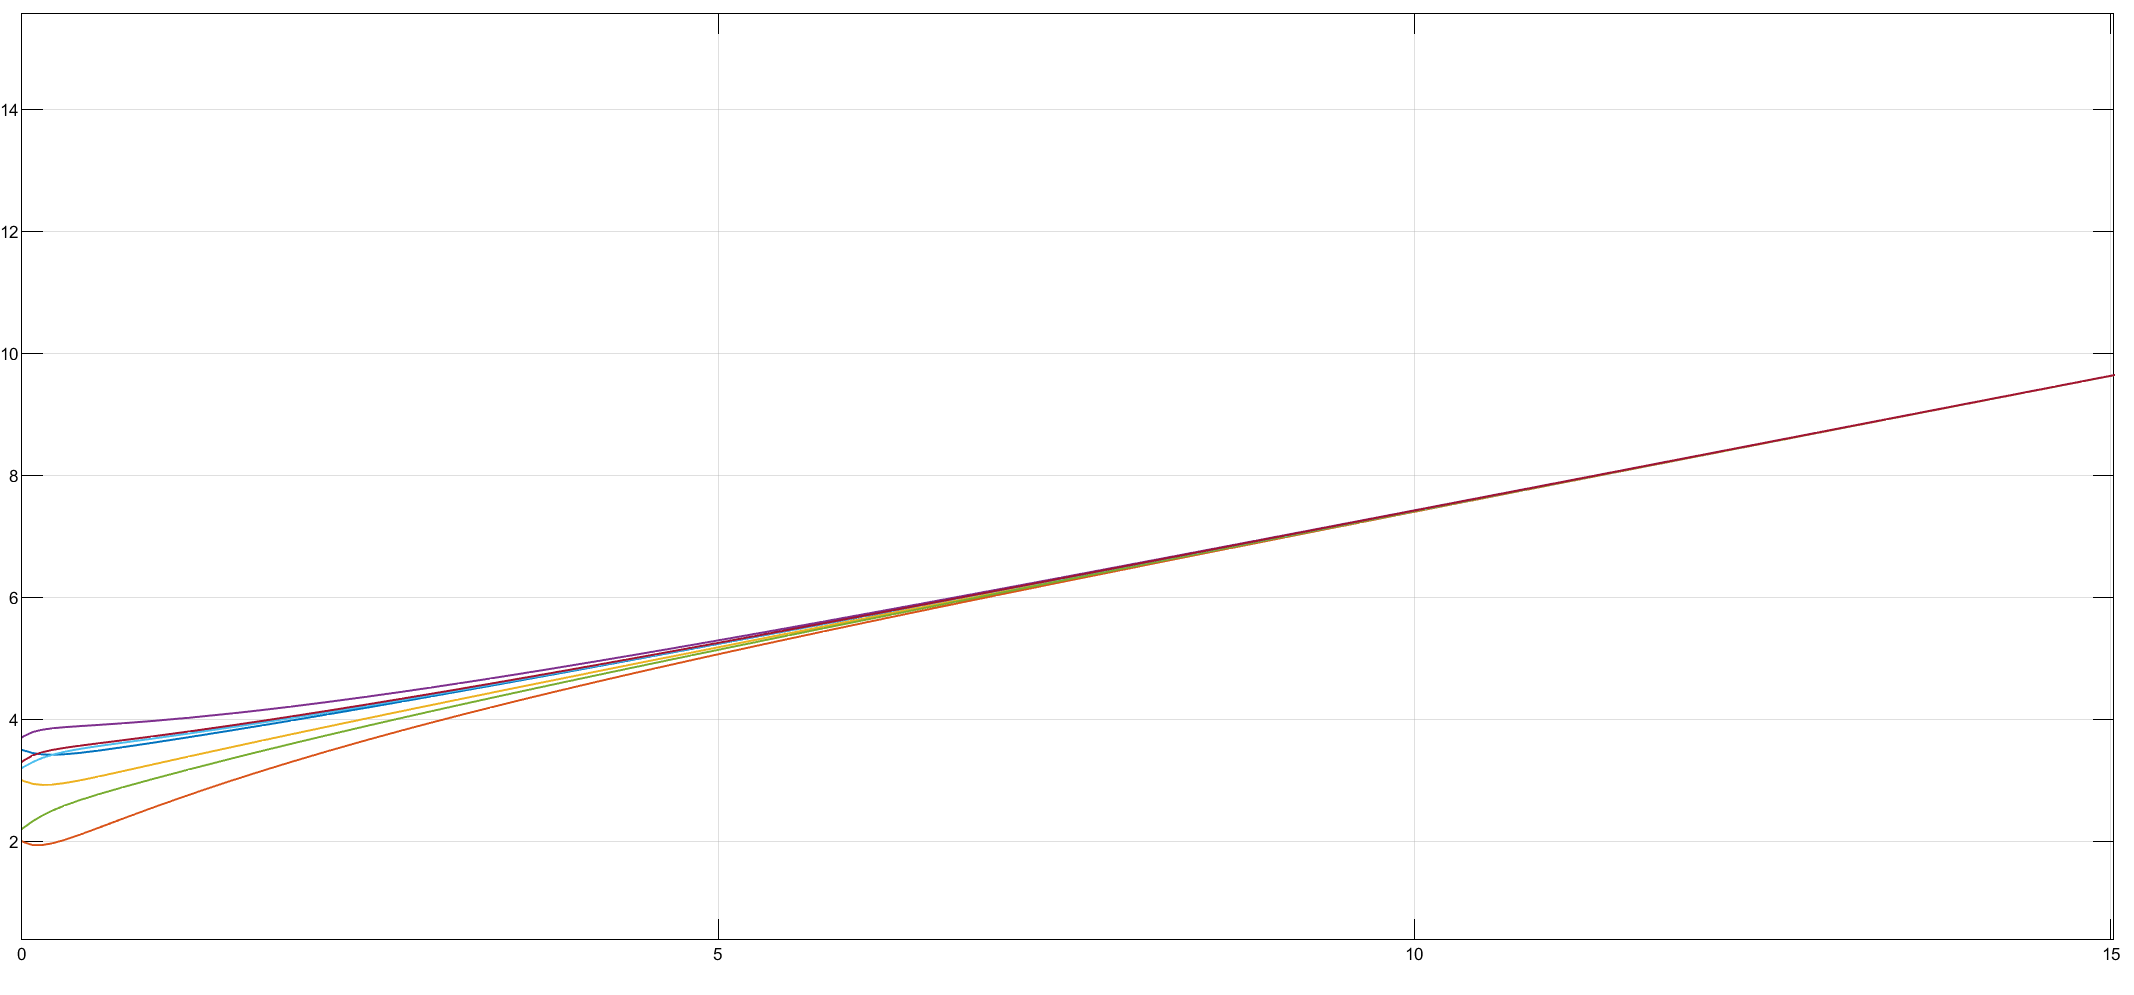


$$x_2 :$$


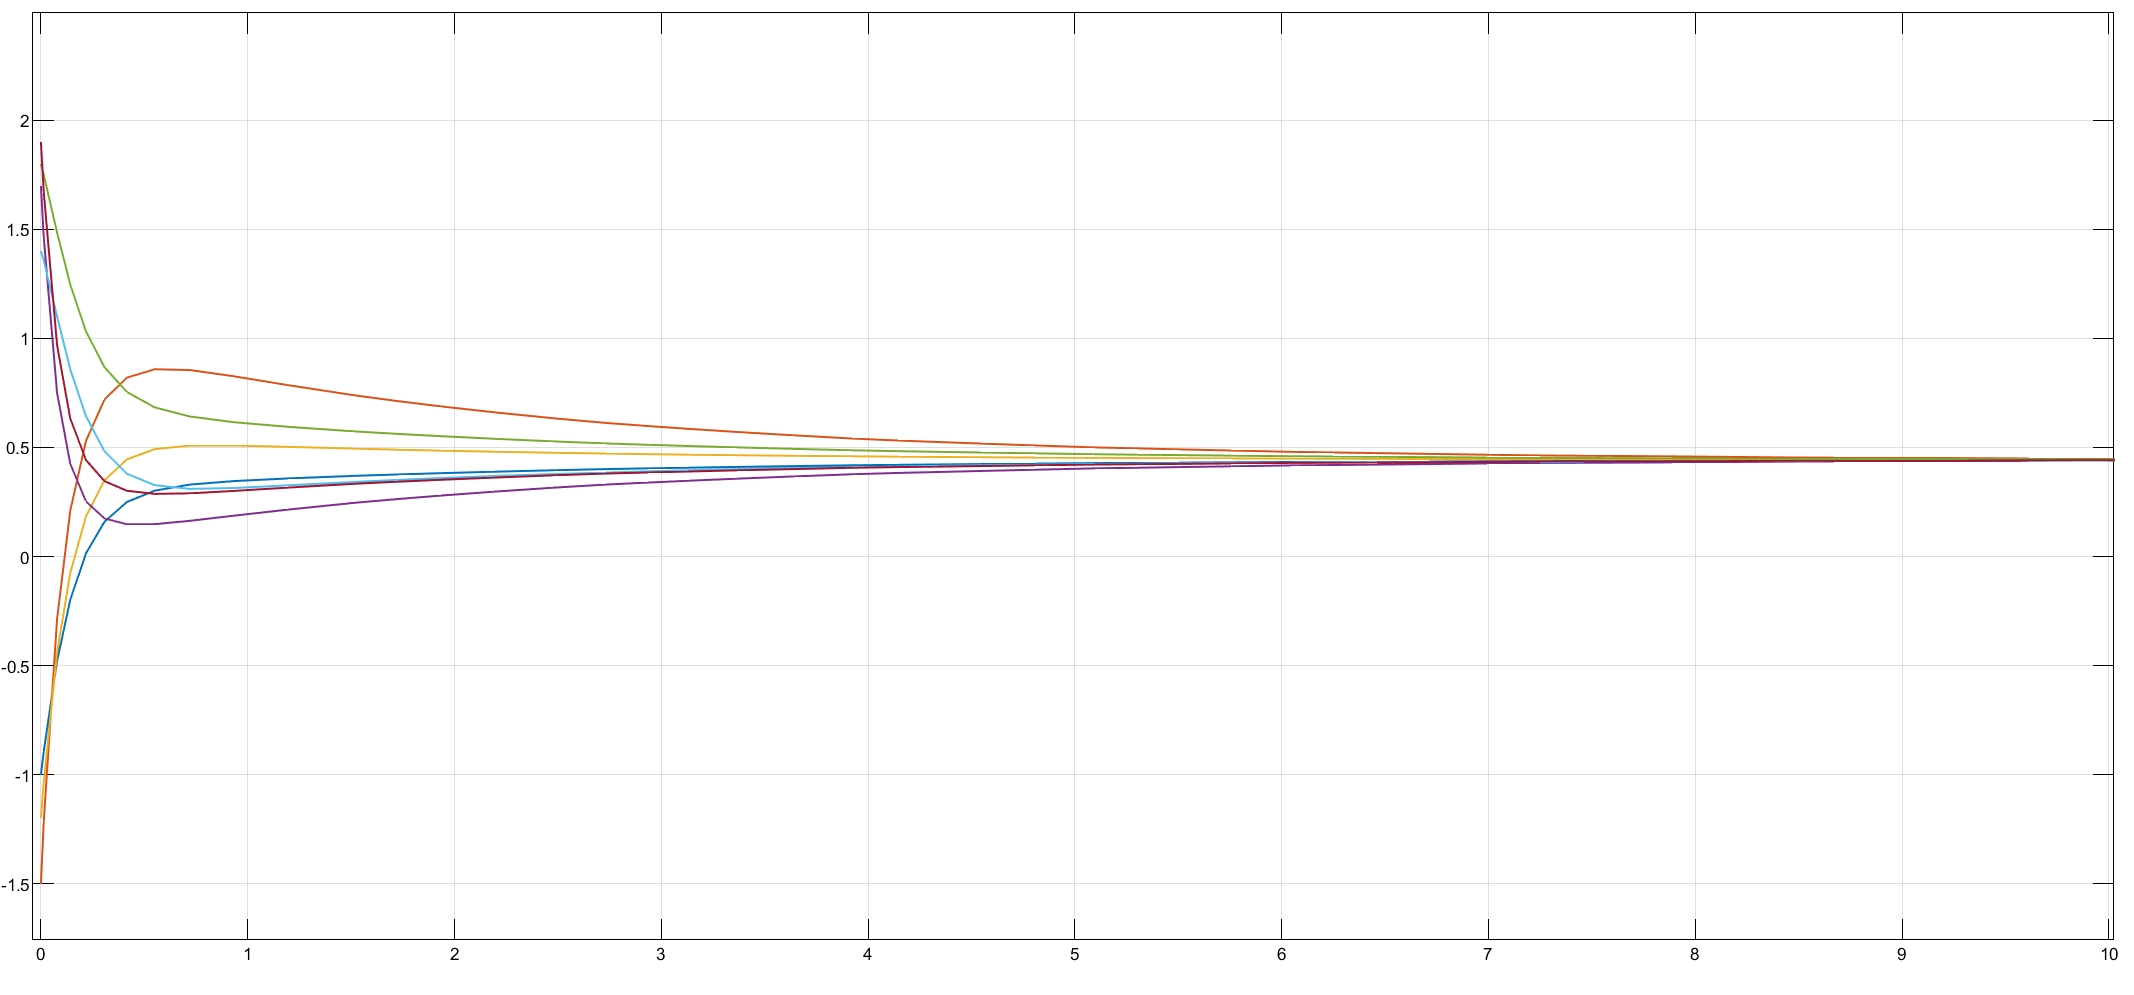

It is observed that in all cases, states are all reached consensus. Comparing $x_2$ state of the three cases shows that the slowest consensus rate is for case 0 where the agents are using their first-order neighbours information. Case I and II have the higher consensus rate. Also Case I reaches the consensus faster than case II since:

- case I

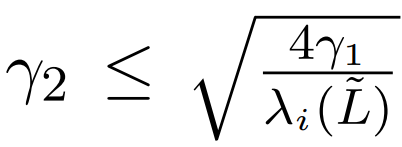

- case II

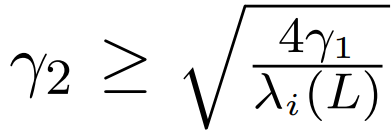

You cound find the consensus rates in the following figure and compare the results.